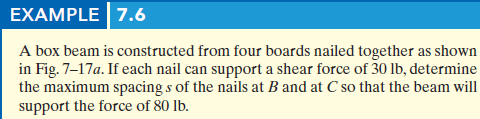

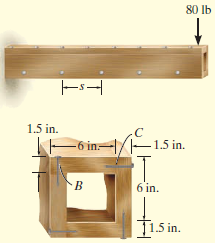

# symbolic units class

u = symunit;

# section properties

yc = [1.5+6-1.5/2, 6/2, 1.5/2, 6/2]*u.in;
Ac = [(6+1.5)*1.5, 1.5*6, (6-1.5)*1.5, 1.5*6]*u.in^2;
Ic = [(6+1.5)*1.5^3, 1.5*6^3, (6-1.5)*1.5^3, 1.5*6^3]/sym(12)*u.in^4;
[yn Qn In] = beam.neutral_axis(yc, Ac, Ic); %#ok
I = sum(In);

# nail spacing

V = 80*u.lbf;
F_nail = 30*u.lbf;
q = V*([Qn(1) -Qn(3)].')/(2*I);
q_vpa = vpa(q, 3) %#ok

$$q\_vpa = \left(\begin{array}{c} 5.88\,\frac{\mathrm{lbf}}{\mathrm{in}}\\ 3.53\,\frac{\mathrm{lbf}}{\mathrm{in}} \end{array}\right)$$

s_nail = rewrite(F_nail./q, u.in);
s_nail_vpa = vpa(s_nail) %#ok

$$s\_nail\_vpa = \left(\begin{array}{c} 5.1\,\mathrm{in}\\ 8.5\,\mathrm{in} \end{array}\right)$$

clear q_vpa s_nail_vpa;